%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Recitation Demo: Numerical ODE Solving, Phase Portraits, and Bifurcations
%
% This script is designed for an in-class MATLAB demonstration.
% Topics:
%  1) Numerical solving + phase portrait for logistic model: x' = a x (1-x)
%  2) Bifurcation diagrams for normal forms: saddle-node, transcritical, pitchfork
%  3) Saddle-node example: x' = r - x - exp(-x)
%  4) Log example (x>0): x' = r*log(x) + x - 1
%  5) Quintic example: x' = r x + x^3 - x^5
%  6) Codim-2 cusp/catastrophe: x' = h + r x - x^3 (catastrophe manifold)
%
% NOTE: All plots are generated from analytic/numerical equilibrium tracking
% and stability classification using f'(x*): stable if f'(x*)<0.
%
% Author: Zhuo-Cheng Xiao
% Date: 01/22/2026
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

%% ================================================================
%  Helper conventions used throughout
%  ------------------------------------------------
%  For a scalar ODE: x' = f(x; params)
%    Equilibrium x* satisfies f(x*;params)=0.
%    Stability: stable if df/dx(x*;params) < 0; unstable if > 0.
%  ------------------------------------------------
%  Plot convention:
%    stable branch:  solid line
%    unstable branch: dashed line
% ================================================================

%% ================================================================
%  1) Logistic model: numerical solving + "phase portrait" (phase line)
%     x' = a x(1-x)
% ================================================================

a = 1;                      % growth rate (try also a<0 to show reversal)
f  = @(t,x) a*x.*(1-x);     % ODE for ode45

tspan = [0 4];
x0_list = [0.05 0.2 0.8 1.2, -1e-4]% -0.2];   % several initial conditions

x0_list =     0.0500    0.2000    0.8000    1.2000   -0.0001


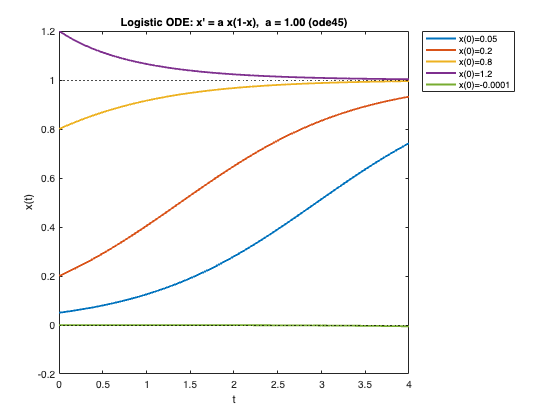


% --- Numerical solutions ---
figure('Name','Logistic: numerical solutions','Color','w');
hold on; box on;
for x0 = x0_list
    [t,x] = ode45(f, tspan, x0);
    plot(t,x,'LineWidth',1.8);
end
yline(0,'k:'); yline(1,'k:');
xlabel('t'); ylabel('x(t)');
title(sprintf('Logistic ODE: x'' = a x(1-x),  a = %.2f (ode45)', a));
legend(arrayfun(@(v) sprintf('x(0)=%.2g',v), x0_list, 'UniformOutput',false), ...
    'Location','bestoutside');

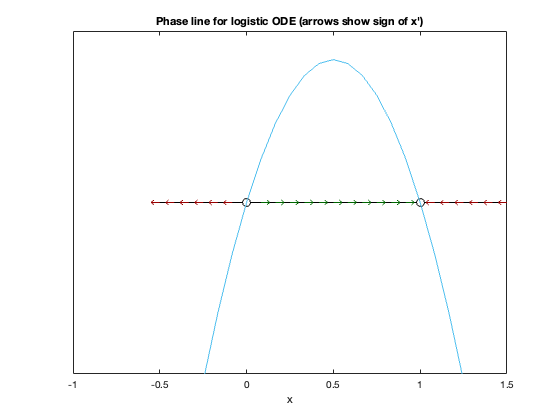


% --- Phase line / vector field on the line ---
% We show arrows indicating direction of flow x increasing/decreasing.
xgrid = linspace(-0.5,1.5,25);
dx = a*xgrid.*(1-xgrid);

figure('Name','Logistic: phase line','Color','w');
hold on; box on;
% Draw the line
plot([min(xgrid) max(xgrid)],[0 0],'k-','LineWidth',1.2);

% Mark equilibria
plot(0,0,'ko','MarkerFaceColor','w','MarkerSize',8);    % x*=0
plot(1,0,'ko','MarkerFaceColor','w','MarkerSize',8);    % x*=1

% Add arrows (scaled) along the line
for i=1:numel(xgrid)
    if dx(i) > 0
        quiver(xgrid(i),0,0.05,0,0,'Color',[0 0.4 0],'LineWidth',1,'MaxHeadSize',1);
    elseif dx(i) < 0
        quiver(xgrid(i),0,-0.05,0,0,'Color',[0.6 0 0],'LineWidth',1,'MaxHeadSize',1);
    else
        % no arrow at equilibrium
    end
end
ylim([-0.3 0.3]);
xlabel('x'); yticks([]);
title('Phase line for logistic ODE (arrows show sign of x'')');

plot(xgrid,dx)

% --- Stability classification by derivative ---
% f(x)=a x(1-x) => f'(x)=a(1-2x)
fp = @(x) a*(1-2*x);
fprintf('\nLogistic equilibria and stability (a=%.2f):\n',a);


Logistic equilibria and stability (a=1.00):


% fprintf('  x*=0:  f''(0)=%.2f  => %s\n', fp(0), ternary(fp(0)<0,'stable','unstable'));
% fprintf('  x*=1:  f''(1)=%.2f  => %s\n', fp(1), ternary(fp(1)<0,'stable','unstable'));